# **The heat equation**

## 1. Introduction

- Let's assume a 1-dimensional rod with length $L>0$ made of an isotropic material,

- The function $T(x,t)$ describes the heat of a point $x$ at time $t$, $x \in [ 0,L ]$, $t \in [0,\infty)$,

- At $t=0$, the rod has some initial heat distribution $T(x,0) = \phi(x)$,

- We assume no heat exchange with the enviornment.

Knowing that, is there a way to know how the heat distribution in the object changes over time? 

## 2. Joseph Fourier's study of heat flow

        *The Analytical Theory of Heat *(fr. *Théorie analytique de la chaleur*) is Fourier's 1822 publication of his work on heat flow. His work was based on Isaac Newton's law of cooling, which states:

*The rate of heat **loss of a body is directly proportional to the difference in the** temperatures **between the body and its environment.*

It is in this book where he famously stated, that any function can be expressed as an infinite sum of sine waves, which led to the invention of the fourier series and later, the fourier transform.


$$\frac{\partial T}{\partial t} = \alpha \cdot \frac{\partial^2 T}{\partial x^2$$


The heat equation for 1 dimension


$$\frac{\partial T}{\partial t} = \alpha \cdot \left( \frac{\partial^2 T}{\partial x^2}+\frac{\partial^2 T}{\partial y^2}+\frac{\partial^2 T}{\partial z^2} \right)$$


## 3. Heat flow in a 1-dimensional rod

Let's first look at an example initial distribution $\phi (x)$

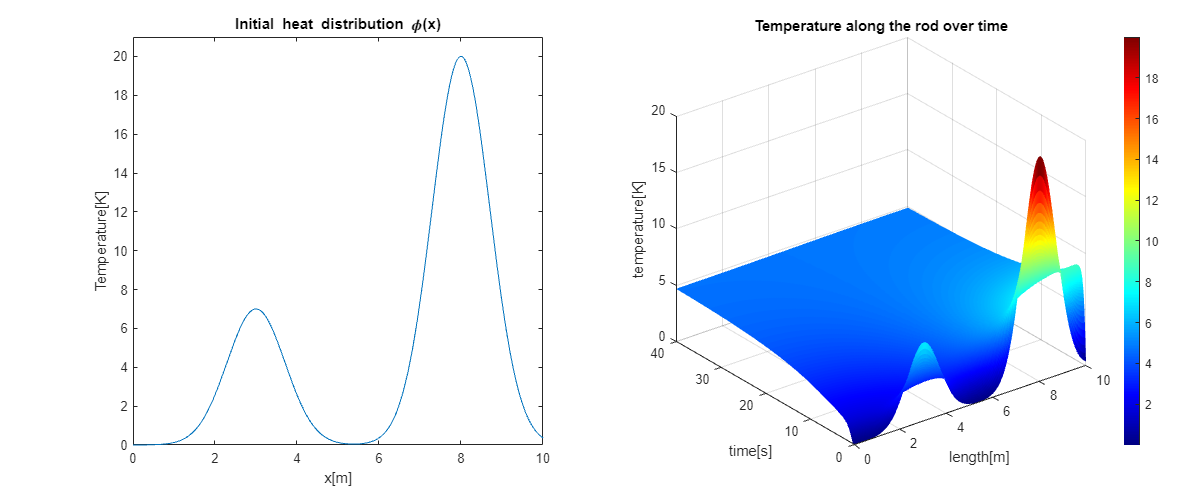

clc;clear;close all
length = 10;
runtime = 40;
first_peak_middle =3;
second_peak_middle = 8;
first_peak_value = 7;
second_peak_value = 20;
syms x
assume(x,"positive")
phi = first_peak_value*exp(-(x-first_peak_middle).^2)+second_peak_value*exp(-(x-second_peak_middle).^2);
global phi_global
phi_global = matlabFunction(phi);


position = linspace(0,length,length*20);
time = linspace(0,runtime,runtime*20);
m = 0;
sol = pdepe(m,@heatpde,@heatic,@heatbc,position,time);

figure('name','Heat_flow_simulation','Position',[400 500 1200 500])

tiledlayout(1,2)
nexttile
grid on
fplot(phi, [0 length]);
xlim([0 length])
ylim([0 max(double(subs(phi,x,first_peak_middle)),double(subs(phi,x,second_peak_middle)))+1])
title("Initial heat distribution \phi(x)")
xlabel("x[m]")
ylabel("Temperature[K]")
colormap('jet')

nexttile
surf(position,time,sol,'EdgeColor','none')
title("Temperature along the rod over time")
xlabel("length[m]")
ylabel("time[s]")
zlabel("temperature[K]")
colormap("jet")
colorbar

function [c,f,s] = heatpde(x,t,u,dudx)
c = 1;
f = dudx;
s = 0;
end
function u0 = heatic(x)
% u0 = 5*exp(-(x-2).^2) + 8*exp(-(x-8).^2) + 5 - 3 * exp(-(x-5).^2);
global phi_global
u0 = phi_global(x);
end
function [pl,ql,pr,qr] = heatbc(xl,ul,xr,ur,t)
pl = 0;
ql = 1;
pr = 0;
qr = 1;
end